# **Problem1: Common Dataset**

**Name: Kim Inyeop  **

### Drive End Bearing Experiment

## 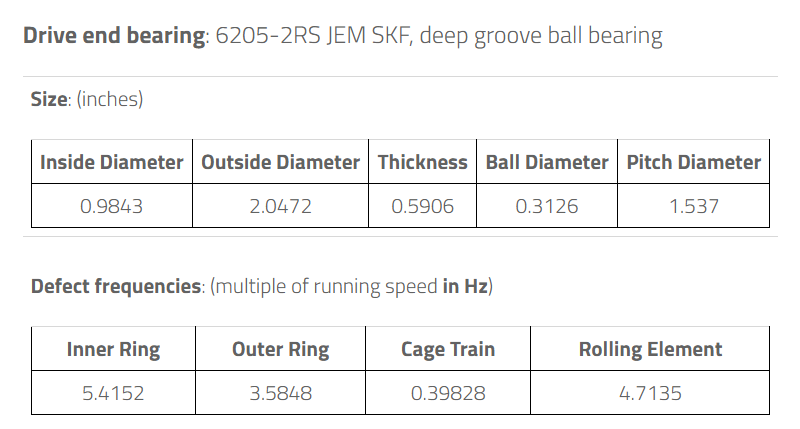

## Load Dataset

close all
clear

load("../../Dataset/HGU_bearing_dataset_v1/HGU_bearing_dataset_v1.mat")
fieldnames(HGU_bearing_dataset_v1)

ans = 6×1 cell 배열
    {'time'         }
    {'bearing_acc'  }
    {'sampling_freq'}
    {'rotating_freq'}
    {'trainset'     }
    {'testset'      }


HGU = HGU_bearing_dataset_v1;



## **Preprocessing**

classes = fieldnames(HGU.trainset);

disp("Complete");

Complete



train_segments = {};
train_labels   = [];

for c = 1:length(classes)
    
    cls = classes{c};
    seg_matrix = HGU.trainset.(cls);   % size = 12000 x 87 (double)
    
    numSeg = size(seg_matrix, 2);      % segment 개수 = 열 개수
    
    for i = 1:numSeg
        % 각 segment는 12000×1 벡터
        segment = seg_matrix(:, i);    

        train_segments{end+1} = segment;
        train_labels(end+1)   = c;
    end
end
size(train_segments)    % → 1×696 cell

ans =      1   696


length(train_labels)    % → 696

ans = 696

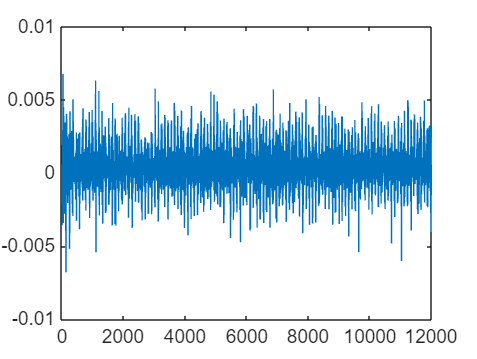


plot(train_segments{1}) % 첫 번째 segment waveform 확인

function feat = statFeature13(x, fs)

    % Input preprocessing
    x = x(:)';          % row vector로 강제
    x = x - mean(x);    % DC offset 제거

    % --- Time domain ---
    rms_val = rms(x);
    sra = sqrt(mean(abs(x)));   
    kurt_val = kurtosis(x);
    skew_val = skewness(x);
    p2p = peak2peak(x);

    crest = max(abs(x)) / rms_val;
    impulse = max(abs(x)) / mean(abs(x));
    margin = max(abs(x)) / sra;
    shape = rms_val / mean(abs(x));
    kurt_factor = kurt_val / (rms_val^4);

    % --- Frequency domain ---
    N = length(x);
    X = abs(fft(x));
    f = (0:N-1)*(fs/N);

    FC  = sum(f .* X) / sum(X);
    RMSF = sqrt(sum((f.^2).*X) / sum(X));
    RVF  = sqrt(sum((f - FC).^2 .* X) / sum(X));

    % return as 1x13 vector
    feat = [rms_val sra kurt_val skew_val p2p ...
            crest impulse margin shape kurt_factor ...
            FC RMSF RVF];
end

fs = HGU.sampling_freq;   % 12000 Hz

numTrain = length(train_segments);
X_train = zeros(numTrain, 13);    % 13 features
y_train = train_labels;           % 레이블 저장 (1~8)

for i = 1:numTrain
    seg = train_segments{i};              % 12000x1 double
    X_train(i, :) = statFeature13(seg, fs);
end

test_segments = {};
test_labels   = [];

classes = fieldnames(HGU.testset);

for c = 1:length(classes)
    cls = classes{c};
    seg_matrix = HGU.testset.(cls);   % double matrix (12000 × 21)
    numSeg = size(seg_matrix, 2);

    for i = 1:numSeg
        test_segments{end+1} = seg_matrix(:, i);
        test_labels(end+1)   = c;
    end
end

numTest = length(test_segments);
X_test = zeros(numTest, 13);
y_test = test_labels;

for i = 1:numTest
    X_test(i, :) = statFeature13(test_segments{i}, fs);
end


## Preprocessing and Feature Extraction(Ball)

function [BPFI, BPFO, BSF] = getFaultFreq(RPM_val)

    % ===== Bearing geometry from HGU Dataset =====
    D1   = 37.05;   % outer race diameter (mm)
    D2   = 24.95;   % inner race diameter (mm)
    NB   = 13;      % number of rolling elements
    Beta = 6.05;    % contact angle (deg)

    % ===== Derived values =====
    Pitch = (D1 + D2) / 2;          % pitch diameter
    Ball  = (D1 - D2) / 2;          % ball diameter
    beta_rad = deg2rad(Beta);       % convert to radians

    % ===== Running speed (Hz) =====
    fr = RPM_val / 60;              % shaft frequency

    % ===== Bearing fault frequencies =====
    BPFI = (NB/2) * fr * (1 + (Ball/Pitch) * cos(beta_rad));
    BPFO = (NB/2) * fr * (1 - (Ball/Pitch) * cos(beta_rad));
    BSF  = (Pitch/(2*Ball)) * fr * (1 - ((Ball/Pitch)*cos(beta_rad))^2);

end


function feat = envFeature_Harm6(seg, fs, RPM_val)

    % Get fault frequencies
    [BPFI, BPFO, BSF] = getFaultFreq(RPM_val);
    fault_list = [BPFI, BPFO, BSF];

    % Preprocess
    x = seg(:)' - mean(seg(:));

    % Hilbert envelope
    env = abs(hilbert(x));

    % Envelope FFT
    N = length(env);
    ENV = abs(fft(env));
    f = (0:N-1)*(fs/N);

    % helper function: amplitude at nearest freq
    function amp = getAmp(target)
        [~, idx] = min(abs(f - target));
        amp = ENV(idx);
    end

    % Extract harmonic features
    feat = [];
    for ff = fault_list     % BPFI, BPFO, BSF
        for h = 1:6         % harmonic 1~6
            amp_val = getAmp(h * ff);
            feat = [feat amp_val];
        end
    end

end


fs = HGU.sampling_freq;    % 12000
RPM_val = 500;             % shaft speed

numTrain = length(train_segments);
X_env_train = zeros(numTrain, 18);   % 18 features

for i = 1:numTrain
    seg = train_segments{i};
    X_env_train(i, :) = envFeature_Harm6(seg, fs, RPM_val);
end
test_feat = envFeature_Harm6(train_segments{1}, fs, RPM_val);

disp(length(test_feat))     % → 반드시 18이 나와야 함

    18



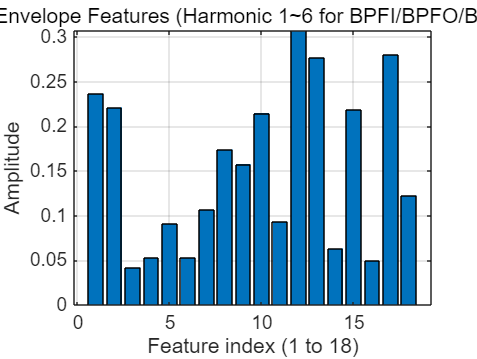

figure;
bar(test_feat);
xlabel("Feature index (1 to 18)");
ylabel("Amplitude");
title("Envelope Features (Harmonic 1~6 for BPFI/BPFO/BSF)");
grid on;

function feat = wpFeature(seg)

    % Ensure row vector
    x = seg(:)';

    % Wavelet Packet parameters
    level = 3;
    wname = 'db4';

    % Decomposition
    wp = wpdec(x, level, wname);

    % Extract energy from 2^level terminal nodes
    numNodes = 2^level;  % = 8
    feat = zeros(1, numNodes);

    for i = 1:numNodes
        node = wpcoef(wp, [level i]);
        feat(i) = sum(node.^2);   % energy
    end

end

test_wave = wpFeature(train_segments{1});
disp(length(test_wave))   % → 반드시 8

     8



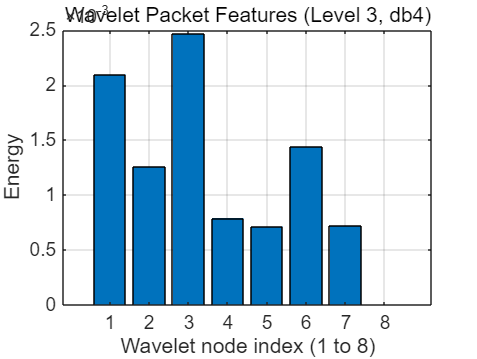

figure;
bar(test_wave);
xlabel("Wavelet node index (1 to 8)");
ylabel("Energy");
title("Wavelet Packet Features (Level 3, db4)");
grid on;

numTrain = length(train_segments);
X_wave_train = zeros(numTrain, 8);

for i = 1:numTrain
    X_wave_train(i, :) = wpFeature(train_segments{i});
end

numTest = length(test_segments);
X_wave_test = zeros(numTest, 8);

for i = 1:numTest
    X_wave_test(i, :) = wpFeature(test_segments{i});
end

function feat_all = extract_all_features(seg, fs, RPM_val)

    % ===== 1) Statistic (13개) =====
    feat_stat = statFeature13(seg, fs);   % 이미 만든 함수

    % ===== 2) Envelope (18개) =====
    feat_env = envFeature_Harm6(seg, fs, RPM_val);  

    % ===== 3) Wavelet Packet (8개) =====
    feat_wave = wpFeature(seg);

    % ===== 4) 통합 =====
    feat_all = [feat_stat, feat_env, feat_wave];

end

fs = HGU.sampling_freq;   % 12000 Hz
RPM = 500;                % 회전 speed

numTrain = length(train_segments);
X_train = zeros(numTrain, 39);

for i = 1:numTrain
    X_train(i, :) = extract_all_features(train_segments{i}, fs, RPM);
end

numTest = length(test_segments);
X_test = zeros(numTest, 39);

for i = 1:numTest
    X_test(i, :) = extract_all_features(test_segments{i}, fs, RPM);
end
size(X_train)   % → [696 39]

ans =    696    39


size(X_test)    % → [168 39]

ans =    168    39


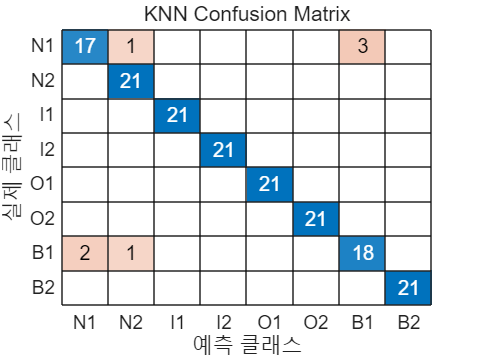

% === 숫자 label -> categorical label로 변환 ===
y_train = categorical(train_labels(:), 1:8, classes);
y_test  = categorical(test_labels(:), 1:8, classes);

% === KNN 학습 ===
knnModel = fitcknn(X_train, y_train, ...
                   'NumNeighbors', 3, ...
                   'Standardize', true);

% === 예측 (label + score) ===
[pred_knn, score_knn] = predict(knnModel, X_test);

% === Confusion Matrix ===
figure;
confusionchart(y_test, pred_knn);
title("KNN Confusion Matrix");


% === Accuracy ===
acc_knn = mean(pred_knn == y_test);
fprintf("KNN Accuracy = %.2f %%\n", acc_knn * 100);

KNN Accuracy = 95.83 %



% =====================================================
% Precision / Recall / F1-score (Macro-average)
% =====================================================
[C, order] = confusionmat(y_test, pred_knn);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2 * (precision(i)*recall(i)) / ...
                   (precision(i) + recall(i) + eps);
end

prec_macro = mean(precision);
rec_macro  = mean(recall);
f1_macro   = mean(f1score);

fprintf("KNN Precision (Macro) = %.4f\n", prec_macro);

KNN Precision (Macro) = 0.9581


fprintf("KNN Recall    (Macro) = %.4f\n", rec_macro);

KNN Recall    (Macro) = 0.9583


fprintf("KNN F1-score  (Macro) = %.4f\n", f1_macro);

KNN F1-score  (Macro) = 0.9577



% =====================================================
% AUC (One-vs-Rest, Macro-average)
% =====================================================
auc_each = zeros(numClasses,1);

for i = 1:numClasses
    % One-vs-Rest binary label
    y_bin = (y_test == order(i));

    % ROC & AUC
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_knn(:,i), true);
end

auc_macro = mean(auc_each);
fprintf("KNN AUC (OvR, Macro) = %.4f\n", auc_macro);

KNN AUC (OvR, Macro) = 0.9862


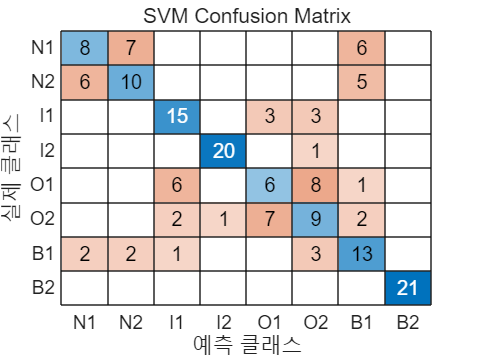

%% ===== SVM =====
t = templateSVM('KernelFunction','rbf', ...
                'KernelScale','auto', ...
                'BoxConstraint', 1);

svmModel = fitcecoc(X_train, y_train, 'Learners', t);

% === 예측 (label + score) ===
[pred_svm, score_svm] = predict(svmModel, X_test);

% === Confusion Matrix ===
figure;
confusionchart(y_test, pred_svm);
title("SVM Confusion Matrix");


% === Accuracy ===
acc_svm = mean(pred_svm == y_test);
fprintf("SVM Accuracy = %.2f %%\n", acc_svm * 100);

SVM Accuracy = 60.71 %



% =====================================================
% Precision / Recall / F1-score (Macro-average)
% =====================================================
[C, order] = confusionmat(y_test, pred_svm);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2 * (precision(i)*recall(i)) / ...
                   (precision(i) + recall(i) + eps);
end

prec_macro = mean(precision);
rec_macro  = mean(recall);
f1_macro   = mean(f1score);

fprintf("SVM Precision (Macro) = %.4f\n", prec_macro);

SVM Precision (Macro) = 0.6044


fprintf("SVM Recall    (Macro) = %.4f\n", rec_macro);

SVM Recall    (Macro) = 0.6071


fprintf("SVM F1-score  (Macro) = %.4f\n", f1_macro);

SVM F1-score  (Macro) = 0.6022



% =====================================================
% AUC (One-vs-Rest, Macro-average)
% =====================================================
auc_each = zeros(numClasses,1);

for i = 1:numClasses
    % One-vs-Rest binary label
    y_bin = (y_test == order(i));

    % ROC & AUC
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_svm(:,i), true);
end

auc_macro = mean(auc_each);
fprintf("SVM AUC (OvR, Macro) = %.4f\n", auc_macro);

SVM AUC (OvR, Macro) = 0.9276


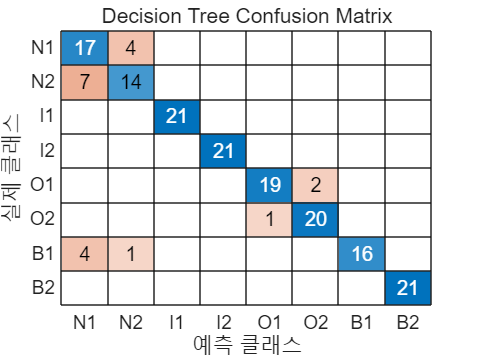

%% ===== Decision Tree =====
dtModel = fitctree(X_train, y_train, 'MinLeafSize', 5);

% === 예측 (label + score) ===
[pred_dt, score_dt] = predict(dtModel, X_test);

% === Confusion Matrix ===
figure;
confusionchart(y_test, pred_dt);
title("Decision Tree Confusion Matrix");


% === Accuracy ===
acc_dt = mean(pred_dt == y_test);
fprintf("Decision Tree Accuracy = %.2f %%\n", acc_dt * 100);

Decision Tree Accuracy = 88.69 %



% =====================================================
% Precision / Recall / F1-score (Macro-average)
% =====================================================
[C, order] = confusionmat(y_test, pred_dt);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2 * (precision(i)*recall(i)) / ...
                   (precision(i) + recall(i) + eps);
end

prec_macro = mean(precision);
rec_macro  = mean(recall);
f1_macro   = mean(f1score);

fprintf("Decision Tree Precision (Macro) = %.4f\n", prec_macro);

Decision Tree Precision (Macro) = 0.9004


fprintf("Decision Tree Recall    (Macro) = %.4f\n", rec_macro);

Decision Tree Recall    (Macro) = 0.8869


fprintf("Decision Tree F1-score  (Macro) = %.4f\n", f1_macro);

Decision Tree F1-score  (Macro) = 0.8895



% =====================================================
% AUC (One-vs-Rest, Macro-average)
% =====================================================
auc_each = zeros(numClasses,1);

for i = 1:numClasses
    % One-vs-Rest binary label
    y_bin = (y_test == order(i));

    % ROC & AUC
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_dt(:,i), true);
end

auc_macro = mean(auc_each);
fprintf("Decision Tree AUC (OvR, Macro) = %.4f\n", auc_macro);

Decision Tree AUC (OvR, Macro) = 0.9770


%% ===== STEP 1: 공통 10-Fold CV 설정 =====
cv = cvpartition(y_train, 'KFold', 10);


%% ===== STEP 2: SFS 용 Loss 함수 정의 =====
% 🔸 SFS는 "Loss"를 최소화하려고 하므로
% mean(predict(...) ~= Yte) = error rate

% --- KNN ---
fun_knn = @(Xtr, Ytr, Xte, Yte) ...
    mean( predict( fitcknn(Xtr, Ytr, ...
                    'NumNeighbors', 3, ...
                    'Standardize', true), ...
            Xte ) ~= Yte );


% --- SVM ---
t = templateSVM('KernelFunction','rbf', ...
                'KernelScale','auto', ...
                'BoxConstraint', 1);

fun_svm = @(Xtr, Ytr, Xte, Yte) ...
    mean( predict( fitcecoc(Xtr, Ytr, 'Learners', t), ...
            Xte ) ~= Yte );


% --- Decision Tree ---
fun_dt = @(Xtr, Ytr, Xte, Yte) ...
    mean( predict( fitctree(Xtr, Ytr, ...
                    'MinLeafSize', 5), ...
            Xte ) ~= Yte );


opts = statset('Display','iter');

[inmodel_knn, history_knn] = sequentialfs(fun_knn, X_train, y_train, ...
    'cv', cv, 'options', opts);

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 5번 열 추가, 기준값 0.00130054
2단계, 8번 열 추가, 기준값 0.000970348
3단계, 36번 열 추가, 기준값 0.000473275
4단계, 32번 열 추가, 기준값 0.000350717
5단계, 3번 열 추가, 기준값 0.000226375
최종적으로 포함된 열: 3 5 8 32 36 


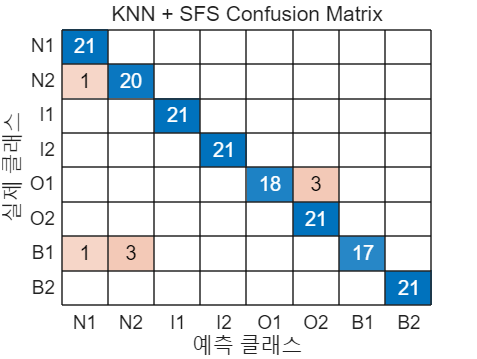

%% ===== KNN (SFS 후) =====

% 선택된 feature subset 적용
X_train_sfs_knn = X_train(:, inmodel_knn);
X_test_sfs_knn  = X_test(:,  inmodel_knn);

% 재학습
knnModel_sfs = fitcknn(X_train_sfs_knn, y_train, ...
                       'NumNeighbors', 3, ...
                       'Standardize', true);

% 예측 (label + score)
[pred_knn_sfs, score_knn_sfs] = predict(knnModel_sfs, X_test_sfs_knn);

% Confusion Matrix
figure;
confusionchart(y_test, pred_knn_sfs);
title("KNN + SFS Confusion Matrix");


% === Accuracy ===
acc_knn_sfs = mean(pred_knn_sfs == y_test);
fprintf("KNN (SFS) Accuracy = %.2f %%\n", acc_knn_sfs * 100);

KNN (SFS) Accuracy = 95.24 %



% =====================================================
% Precision / Recall / F1-score (Macro-average)
% =====================================================
[C, order] = confusionmat(y_test, pred_knn_sfs);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2 * (precision(i)*recall(i)) / ...
                   (precision(i) + recall(i) + eps);
end

prec_macro = mean(precision);
rec_macro  = mean(recall);
f1_macro   = mean(f1score);

fprintf("KNN (SFS) Precision (Macro) = %.4f\n", prec_macro);

KNN (SFS) Precision (Macro) = 0.9572


fprintf("KNN (SFS) Recall    (Macro) = %.4f\n", rec_macro);

KNN (SFS) Recall    (Macro) = 0.9524


fprintf("KNN (SFS) F1-score  (Macro) = %.4f\n", f1_macro);

KNN (SFS) F1-score  (Macro) = 0.9518



% =====================================================
% AUC (One-vs-Rest, Macro-average)
% =====================================================
auc_each = zeros(numClasses,1);

for i = 1:numClasses
    % One-vs-Rest binary label
    y_bin = (y_test == order(i));

    % ROC & AUC
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_knn_sfs(:,i), true);
end

auc_macro = mean(auc_each);
fprintf("KNN (SFS) AUC (OvR, Macro) = %.4f\n", auc_macro);

KNN (SFS) AUC (OvR, Macro) = 0.9869



% === Feature count ===
fprintf("KNN SFS selected features: %d\n", sum(inmodel_knn));

KNN SFS selected features: 5


opts = statset('Display','iter');     % or 'iter-detailed'

[inmodel_svm, history_svm] = sequentialfs(fun_svm, X_train, y_train, ...
    'cv', cv, 'options', opts, 'direction', 'forward');

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 5번 열 추가, 기준값 0.00362973
2단계, 2번 열 추가, 기준값 0.00111343
3단계, 35번 열 추가, 기준값 0.000824588
4단계, 34번 열 추가, 기준값 0.000680315
5단계, 38번 열 추가, 기준값 0.000618143
6단계, 32번 열 추가, 기준값 0.000453345
7단계, 37번 열 추가, 기준값 0.000412591
8단계, 36번 열 추가, 기준값 0.000392066
최종적으로 포함된 열: 2 5 32 34 35 36 37 38 


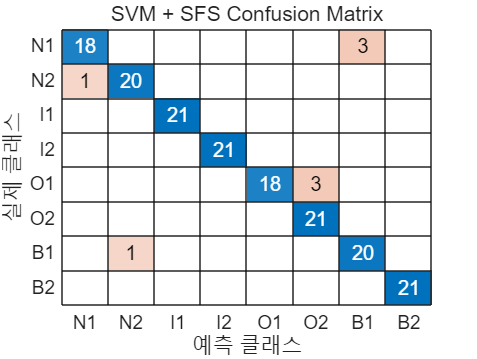


%% ===== SVM (SFS 후) =====

% 선택된 feature subset 적용
X_train_sfs_svm = X_train(:, inmodel_svm);
X_test_sfs_svm  = X_test(:,  inmodel_svm);

% 재학습
svmModel_sfs = fitcecoc(X_train_sfs_svm, y_train, 'Learners', t);

% 예측 (label + score)
[pred_svm_sfs, score_svm_sfs] = predict(svmModel_sfs, X_test_sfs_svm);

% Confusion Matrix
figure;
confusionchart(y_test, pred_svm_sfs);
title("SVM + SFS Confusion Matrix");


% === Accuracy ===
acc_svm_sfs = mean(pred_svm_sfs == y_test);
fprintf("SVM (SFS) Accuracy = %.2f %%\n", acc_svm_sfs * 100);

SVM (SFS) Accuracy = 95.24 %



% =====================================================
% Precision / Recall / F1-score (Macro-average)
% =====================================================
[C, order] = confusionmat(y_test, pred_svm_sfs);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2 * (precision(i)*recall(i)) / ...
                   (precision(i) + recall(i) + eps);
end

prec_macro = mean(precision);
rec_macro  = mean(recall);
f1_macro   = mean(f1score);

fprintf("SVM (SFS) Precision (Macro) = %.4f\n", prec_macro);

SVM (SFS) Precision (Macro) = 0.9555


fprintf("SVM (SFS) Recall    (Macro) = %.4f\n", rec_macro);

SVM (SFS) Recall    (Macro) = 0.9524


fprintf("SVM (SFS) F1-score  (Macro) = %.4f\n", f1_macro);

SVM (SFS) F1-score  (Macro) = 0.9522



% =====================================================
% AUC (One-vs-Rest, Macro-average)
% =====================================================
auc_each = zeros(numClasses,1);

for i = 1:numClasses
    % One-vs-Rest binary label
    y_bin = (y_test == order(i));

    % ROC & AUC
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_svm_sfs(:,i), true);
end

auc_macro = mean(auc_each);
fprintf("SVM (SFS) AUC (OvR, Macro) = %.4f\n", auc_macro);

SVM (SFS) AUC (OvR, Macro) = 0.9914



% === Feature count ===
fprintf("SVM SFS selected features: %d\n", sum(inmodel_svm));

SVM SFS selected features: 8


%% ===== Decision Tree (SFS 후) =====

[inmodel_dt, history_dt] = sequentialfs(fun_dt, X_train, y_train, ...
    'cv', cv, 'options', opts);

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 5번 열 추가, 기준값 0.00259989
2단계, 7번 열 추가, 기준값 0.000949823
3단계, 34번 열 추가, 기준값 0.000868018
4단계, 1번 열 추가, 기준값 0.000702327
5단계, 19번 열 추가, 기준값 0.00059851
6단계, 35번 열 추가, 기준값 0.000536636
최종적으로 포함된 열: 1 5 7 19 34 35 


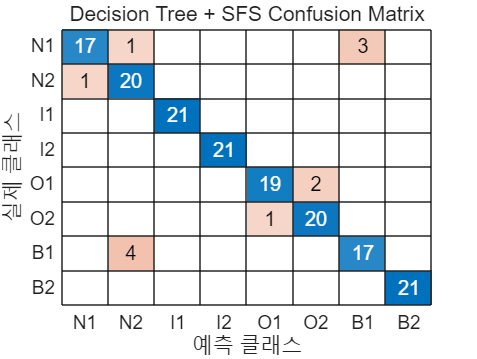

%% ===== Decision Tree (SFS 후) =====

% 선택된 feature subset 적용
X_train_sfs_dt = X_train(:, inmodel_dt);
X_test_sfs_dt  = X_test(:,  inmodel_dt);

% 재학습
dtModel_sfs = fitctree(X_train_sfs_dt, y_train, 'MinLeafSize', 5);

% 예측 (label + score)
[pred_dt_sfs, score_dt_sfs] = predict(dtModel_sfs, X_test_sfs_dt);

% Confusion Matrix
figure;
confusionchart(y_test, pred_dt_sfs);
title("Decision Tree + SFS Confusion Matrix");


% === Accuracy ===
acc_dt_sfs = mean(pred_dt_sfs == y_test);
fprintf("Decision Tree (SFS) Accuracy = %.2f %%\n", acc_dt_sfs * 100);

Decision Tree (SFS) Accuracy = 92.86 %



% =====================================================
% Precision / Recall / F1-score (Macro-average)
% =====================================================
[C, order] = confusionmat(y_test, pred_dt_sfs);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2 * (precision(i)*recall(i)) / ...
                   (precision(i) + recall(i) + eps);
end

prec_macro = mean(precision);
rec_macro  = mean(recall);
f1_macro   = mean(f1score);

fprintf("Decision Tree (SFS) Precision (Macro) = %.4f\n", prec_macro);

Decision Tree (SFS) Precision (Macro) = 0.9317


fprintf("Decision Tree (SFS) Recall    (Macro) = %.4f\n", rec_macro);

Decision Tree (SFS) Recall    (Macro) = 0.9286


fprintf("Decision Tree (SFS) F1-score  (Macro) = %.4f\n", f1_macro);

Decision Tree (SFS) F1-score  (Macro) = 0.9285



% =====================================================
% AUC (One-vs-Rest, Macro-average)
% =====================================================
auc_each = zeros(numClasses,1);

for i = 1:numClasses
    % One-vs-Rest binary label
    y_bin = (y_test == order(i));

    % ROC & AUC
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_dt_sfs(:,i), true);
end

auc_macro = mean(auc_each);
fprintf("Decision Tree (SFS) AUC (OvR, Macro) = %.4f\n", auc_macro);

Decision Tree (SFS) AUC (OvR, Macro) = 0.9715



% === Feature count ===
fprintf("Decision Tree SFS selected features: %d\n", sum(inmodel_dt));

Decision Tree SFS selected features: 6


var_all = var(X_train);
disp(var_all);

   1.0e+24 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.1557    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0



fprintf("=== Non-zero variance feature index ===\n");

=== Non-zero variance feature index ===


find(var_all > 1e-12)

ans =      1     2     3     4     5     6     7     8     9    10    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38


mu = mean(X_train,1);          % 각 feature의 평균
sigma = std(X_train,0,1);      % 각 feature의 표준편차

X_train_std = (X_train - mu) ./ sigma;
X_test_std  = (X_test  - mu) ./ sigma;
mean(X_train_std)

ans =     0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0201   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000       NaN


var(X_train_std)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9996    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000       NaN


%% ================================
% STEP 0 — Log transform + Z-score
% ================================
X_train_log = log1p(abs(X_train));
X_test_log  = log1p(abs(X_test));

mu = mean(X_train_log, 1);
sigma = std(X_train_log, 0, 1);

X_train_scaled = (X_train_log - mu) ./ sigma;
X_test_scaled  = (X_test_log  - mu) ./ sigma;

%% ================================
% STEP 1 — Remove zero-variance features
% ================================
var_feat = var(X_train_scaled, 0, 1);

idx_nonzero = var_feat > 1e-6;   % 너무 작은 variance는 제거
X_train_v1 = X_train_scaled(:, idx_nonzero);
X_test_v1  = X_test_scaled(:, idx_nonzero);

fprintf("Zero-variance 제거 후 feature 수 = %d → %d\n", ...
        size(X_train_scaled,2), size(X_train_v1,2));

Zero-variance 제거 후 feature 수 = 39 → 38


%% =======================================
% STEP 2 — Remove highly correlated feats
% =======================================
R = corr(X_train_v1);
upperR = triu(R, 1);

[idx_i, idx_j] = find(abs(upperR) > 0.95);

removeList = unique(idx_j);

X_train_v2 = X_train_v1;
X_test_v2  = X_test_v1;

X_train_v2(:, removeList) = [];
X_test_v2(:, removeList)  = [];

fprintf("High-correlation 제거 후 feature 수 = %d → %d\n", ...
        size(X_train_v1,2), size(X_train_v2,2));

High-correlation 제거 후 feature 수 = 38 → 31


%% ================================
% STEP 3 — PCA (자동 차원 선택)
% ================================
[coeff, score_train, latent, ~, explained] = pca(X_train_v2);

cumExp = cumsum(explained);
k_opt = find(cumExp >= 95, 1);  % 필요한 최소 차원

fprintf("PCA 자동 선택 차원 = %d (누적 분산 %.2f%%)\n", ...
    k_opt, cumExp(k_opt));

PCA 자동 선택 차원 = 18 (누적 분산 95.54%)



X_train_pca = score_train(:, 1:k_opt);

% Test set 변환
X_test_pca = (X_test_v2 - mean(X_train_v2)) * coeff(:, 1:k_opt);

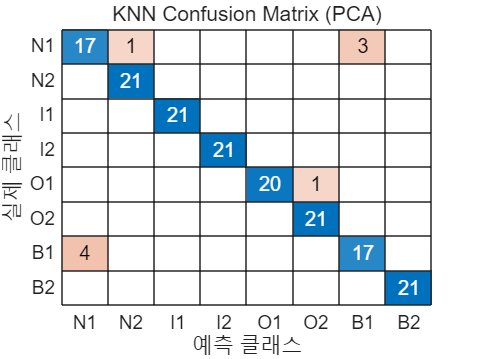

%% ===== KNN (PCA 적용) =====
knnModel_pca = fitcknn(X_train_pca, y_train, ...
                       'NumNeighbors', 3);

% 예측 (label + score)
[pred_knn_pca, score_knn_pca] = predict(knnModel_pca, X_test_pca);

% Confusion Matrix
figure;
confusionchart(y_test, pred_knn_pca);
title("KNN Confusion Matrix (PCA)");


% Accuracy
acc_knn_pca = mean(pred_knn_pca == y_test);
fprintf("KNN Accuracy (PCA) = %.2f %%\n", acc_knn_pca * 100);

KNN Accuracy (PCA) = 94.64 %



% ===== Precision / Recall / F1 (Macro) =====
[C, order] = confusionmat(y_test, pred_knn_pca);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2*(precision(i)*recall(i)) / ...
                   (precision(i)+recall(i)+eps);
end

fprintf("KNN Precision (Macro, PCA) = %.4f\n", mean(precision));

KNN Precision (Macro, PCA) = 0.9461


fprintf("KNN Recall    (Macro, PCA) = %.4f\n", mean(recall));

KNN Recall    (Macro, PCA) = 0.9464


fprintf("KNN F1-score  (Macro, PCA) = %.4f\n", mean(f1score));

KNN F1-score  (Macro, PCA) = 0.9460



% ===== AUC (OvR, Macro) =====
auc_each = zeros(numClasses,1);
for i = 1:numClasses
    y_bin = (y_test == order(i));
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_knn_pca(:,i), true);
end
fprintf("KNN AUC (OvR, PCA) = %.4f\n", mean(auc_each));

KNN AUC (OvR, PCA) = 0.9851


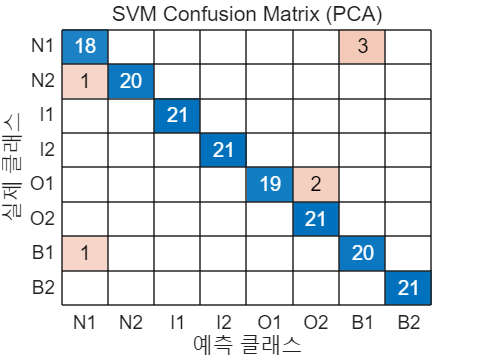

%% ===== SVM (PCA 적용) =====
t = templateSVM('KernelFunction','rbf', ...
                'KernelScale','auto');

svmModel_pca = fitcecoc(X_train_pca, y_train, 'Learners', t);

% 예측 (label + score)
[pred_svm_pca, score_svm_pca] = predict(svmModel_pca, X_test_pca);

% Confusion Matrix
figure;
confusionchart(y_test, pred_svm_pca);
title("SVM Confusion Matrix (PCA)");


% Accuracy
acc_svm_pca = mean(pred_svm_pca == y_test);
fprintf("SVM Accuracy (PCA) = %.2f %%\n", acc_svm_pca * 100);

SVM Accuracy (PCA) = 95.83 %



% ===== Precision / Recall / F1 (Macro) =====
[C, order] = confusionmat(y_test, pred_svm_pca);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2*(precision(i)*recall(i)) / ...
                   (precision(i)+recall(i)+eps);
end

fprintf("SVM Precision (Macro, PCA) = %.4f\n", mean(precision));

SVM Precision (Macro, PCA) = 0.9603


fprintf("SVM Recall    (Macro, PCA) = %.4f\n", mean(recall));

SVM Recall    (Macro, PCA) = 0.9583


fprintf("SVM F1-score  (Macro, PCA) = %.4f\n", mean(f1score));

SVM F1-score  (Macro, PCA) = 0.9584



% ===== AUC (OvR, Macro) =====
auc_each = zeros(numClasses,1);
for i = 1:numClasses
    y_bin = (y_test == order(i));
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_svm_pca(:,i), true);
end
fprintf("SVM AUC (OvR, PCA) = %.4f\n", mean(auc_each));

SVM AUC (OvR, PCA) = 0.9964


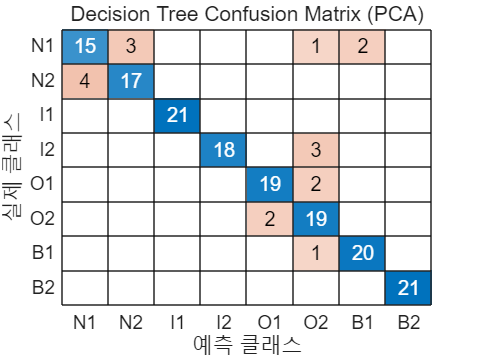

%% ===== Decision Tree (PCA 적용) =====
dtModel_pca = fitctree(X_train_pca, y_train);

% 예측 (label + score)
[pred_dt_pca, score_dt_pca] = predict(dtModel_pca, X_test_pca);

% Confusion Matrix
figure;
confusionchart(y_test, pred_dt_pca);
title("Decision Tree Confusion Matrix (PCA)");


% Accuracy
acc_dt_pca = mean(pred_dt_pca == y_test);
fprintf("Decision Tree Accuracy (PCA) = %.2f %%\n", acc_dt_pca * 100);

Decision Tree Accuracy (PCA) = 89.29 %



% ===== Precision / Recall / F1 (Macro) =====
[C, order] = confusionmat(y_test, pred_dt_pca);
numClasses = size(C,1);

precision = zeros(numClasses,1);
recall    = zeros(numClasses,1);
f1score   = zeros(numClasses,1);

for i = 1:numClasses
    TP = C(i,i);
    FP = sum(C(:,i)) - TP;
    FN = sum(C(i,:)) - TP;

    precision(i) = TP / (TP + FP + eps);
    recall(i)    = TP / (TP + FN + eps);
    f1score(i)   = 2*(precision(i)*recall(i)) / ...
                   (precision(i)+recall(i)+eps);
end

fprintf("DT Precision (Macro, PCA) = %.4f\n", mean(precision));

DT Precision (Macro, PCA) = 0.8980


fprintf("DT Recall    (Macro, PCA) = %.4f\n", mean(recall));

DT Recall    (Macro, PCA) = 0.8929


fprintf("DT F1-score  (Macro, PCA) = %.4f\n", mean(f1score));

DT F1-score  (Macro, PCA) = 0.8932



% ===== AUC (OvR, Macro) =====
auc_each = zeros(numClasses,1);
for i = 1:numClasses
    y_bin = (y_test == order(i));
    [~,~,~,auc_each(i)] = perfcurve(y_bin, score_dt_pca(:,i), true);
end
fprintf("DT AUC (OvR, PCA) = %.4f\n", mean(auc_each));

DT AUC (OvR, PCA) = 0.9534
